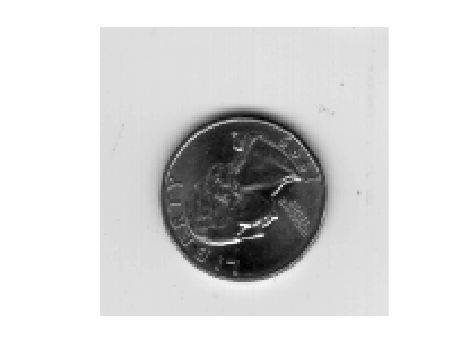

clear all;
% Image enhancement I - Exercise III (histogram specification)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% PARAMETERS

load('quarter.mat');
quarter = double(quarter);
imshow(quarter, [], 'InitialMagnification', 'fit')


upperlimit_in  = 160   % The guess that the coin is between 0-upperlimit_in

upperlimit_in = 160


upperlimit_out = 180   % The new grayscale range for the coin is 0-upperlimit_out

upperlimit_out = 180

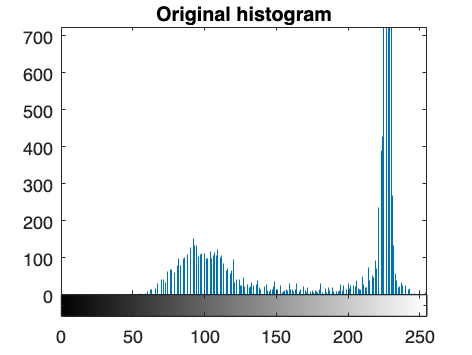

% Compute the original image PDF and CDF:

% PDF: 

[pdf_orig, bin_orig] = imhist( uint8(quarter), 256);
imhist( uint8(quarter) , 256);
title("Original histogram")

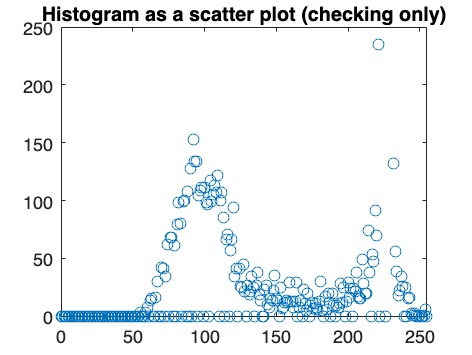


pdf_orig = double(pdf_orig);

plot(bin_orig, pdf_orig, 'o')
ylim([0 250])
xlim([0 255])
title("Histogram as a scatter plot (checking only)")

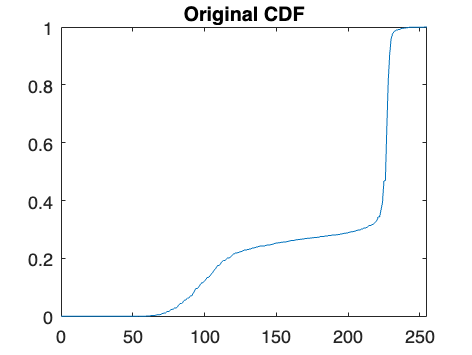


% CDF:

cdf = cumsum(pdf_orig);
cdf = cdf / max(cdf);

plot(bin_orig, cdf)
title("Original CDF")
xlim([0 255])

% Prepare the target PDF and CDF:

% the target PDF (histogram) is a step function. The height of the
% histogram depends on the amount of data below and above upperlimit_in.

N_below = sum( quarter <= upperlimit_in, "all");
N_above = sum( quarter >  upperlimit_in, "all");
disp('Fraction of pixels below upperlimit_in:')

Fraction of pixels below upperlimit_in:


N_below / (N_above + N_below)

ans = 0.2610

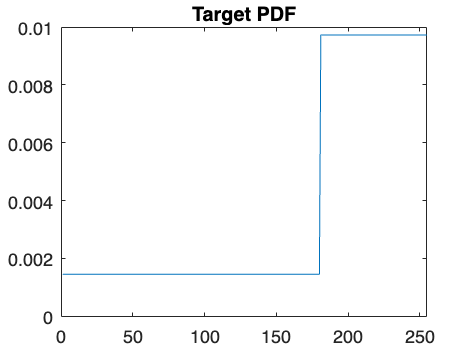


pdf_new    = pdf_orig;
pdf_new(1:upperlimit_out    ) = N_below / (N_below+N_above) / upperlimit_out;
pdf_new(upperlimit_out+1:end) = N_above / (N_below+N_above) / (256-upperlimit_out);

% Plot the target PDF

pdf_new = pdf_new / sum(pdf_new, "all");

plot(pdf_new);
title("Target PDF")
xlim([0, 255])


sum(pdf_new, "all")    % Sanity check -- should be one.

ans = 1

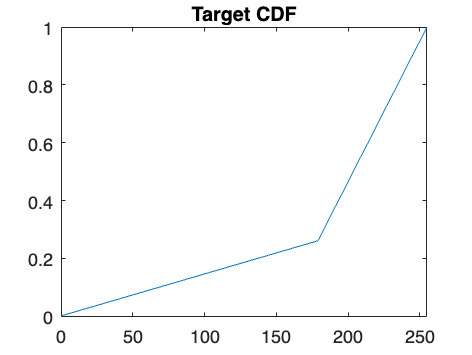


% Create and plot the target cdf:

cdf_new    = cumsum(pdf_new);

cdf_new = cdf_new / max(cdf_new);

plot(bin_orig, cdf_new)
title("Target CDF")
xlim([0, 255])

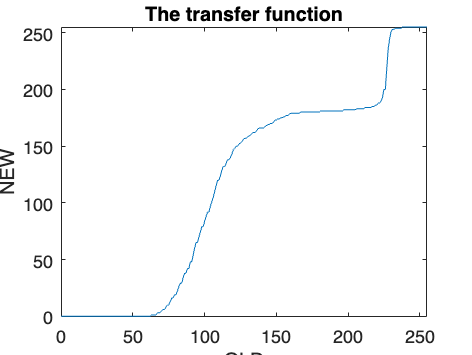

% We now have the original and target cdfs. 
% Then, for each bin value (grayscale), find out the 
% original probability and the new grayscale it corresponds to.

gray_orig = 0:1:255;
gray_new  = gray_orig;
gray_new(:) = 0;

for i = 1:256

    p_old = cdf( i );

    dists = abs(cdf_new - p_old);

    [ind_new] = bin_orig( find(dists == min(dists)) );

%     if p_old > 0
%         i
%         disp('Probability: ')
%         p_old
%         disp('... Maps to the grayscale: ')
%         bin_orig(ind_new+1) * 255
%     end

    gray_new(i) = bin_orig(ind_new(1)+1);

end

plot(gray_orig, gray_new) % The transfer function
title("The transfer function")
xlim([0 255])
ylim([0 255])
xlabel("OLD")
ylabel("NEW")

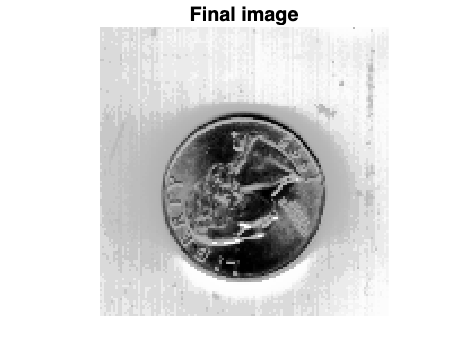

% Then prepare the final image. 

quarter_specified = gray_new(quarter+1);

imshow(quarter_specified, [1 256], 'InitialMagnification', 'fit')
title("Final image")

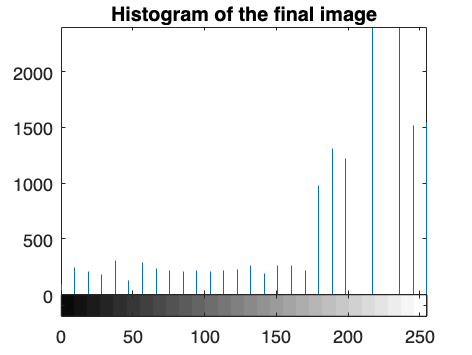


imhist( uint8(quarter_specified), 28)
title("Histogram of the final image")

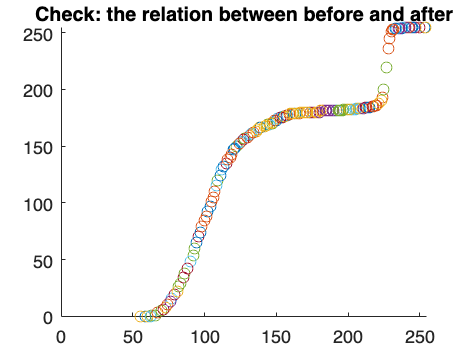


% Check that the relation between the original and specified images
% indeed looks like the transfer function

scatter(quarter, quarter_specified)
title('Check: the relation between before and after')
xlim([0 255])
ylim([0 255])